# The inequality of flood duration at global scales

## Merge data of flood events and groups of country

The Data structure of flood events with country and country groups

- Type: Table

`myTable.Properties.VariableNames`

In the sheet "List of economies",	the column "code", "Region", and "Income group" from row 2 to 219 indicate the country code, region group and income group.

In the sheet "EM-DAT Data",	the column "ISO" and "Duration" from row 2 to end indicate the country code and flood duration of each flood event. Can you help me reture a table just like "EM-DAT Data", but with the region group and income group of the country of each each event. The "ISO" in table 2 and "code" in table 1 is the key to merge.

(A better way: maybe I should download the list of economies and their groups in each year, and then merger the flood events accroding to the groups in the year the event occured.)

Final data: E:\code\Py_workplace\satellite_flooding\test_poverty_flooding_duration\global_evidence\EMDAT_world_duration_group.mat

clc
clear

load("E:\code\Py_workplace\satellite_flooding\test_poverty_flooding_duration\global_evidence\EMDAT_world_duration_group.mat")

region_div = clean_table_return_array(EMDAT_world_duration_group.Region1);
econo_div = clean_table_return_array(EMDAT_world_duration_group.IncomeGroup);
country_div = clean_table_return_array(EMDAT_world_duration_group.ISO);




## The difference of flood duration across different regions

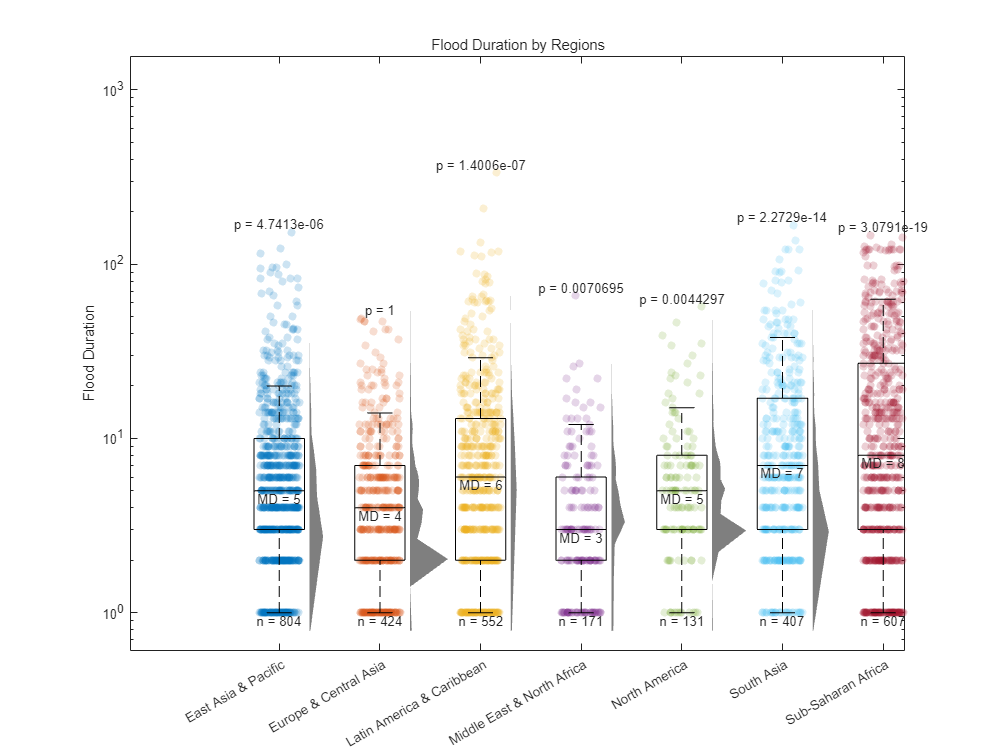


duration_by_region = containers.Map('KeyType', 'char', 'ValueType', 'any');
N_event_by_region = zeros(length(region_div),1);


% Loop through each category in region_div
for i = 1:length(region_div)
    % Get the current region name as a string
    current_region = char(region_div(i));
    
    % Find the rows in the table that match the current region
    logic_in = (EMDAT_world_duration_group.Region1 == region_div(i));
    
    % Extract the 'Duration' data for the current region
    duration_data = EMDAT_world_duration_group.Duration(logic_in);
    duration_data = duration_data(duration_data>=1);
    N_event_by_region(i) = length(duration_data);
    % Add the duration data to the map with the region as the key
    duration_by_region(current_region) = duration_data;
end

N_event = sum(N_event_by_region);
figure
draw_boxplot_density_scatter(duration_by_region,N_event)
% Labels and Title
ylabel('Flood Duration');
title('Flood Duration by Regions');

% Increase figure size for better visibility
set(gcf, 'Position', [100, 100, 800, 600]);



% Example annotations - you will need to calculate these values based on your data


% Loop through each category in region_div
p_values = N_event_by_region*0;
md_values = N_event_by_region*0;

base_duration = duration_by_region('Europe & Central Asia');
for i = 1:length(region_div)
    % Get the current region name as a string
    current_region = char(region_div(i));
    
    p_values(i) = ranksum(base_duration, duration_by_region(current_region));
    md_values(i) = median(duration_by_region(current_region));


end


% p_values = [8.2e-08, 0.00054, 8.3e-07, 0.47];
% md_values = [9, 3, 4, 1];
n_values = N_event_by_region;

% Loop to add p-values and MDs to the plot
for i = 1:length(region_div)
    % Get the current region name as a string
    current_region = char(region_div(i));
    data_i = duration_by_region(current_region);
    text(i, max(data_i), ['p = ' num2str(p_values(i))], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
    text(i, median(data_i), ['MD = ' num2str(md_values(i))], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top');
    text(i, min(data_i), ['n = ' num2str(n_values(i))], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'cap');
end

## The difference of flood duration across different income groups

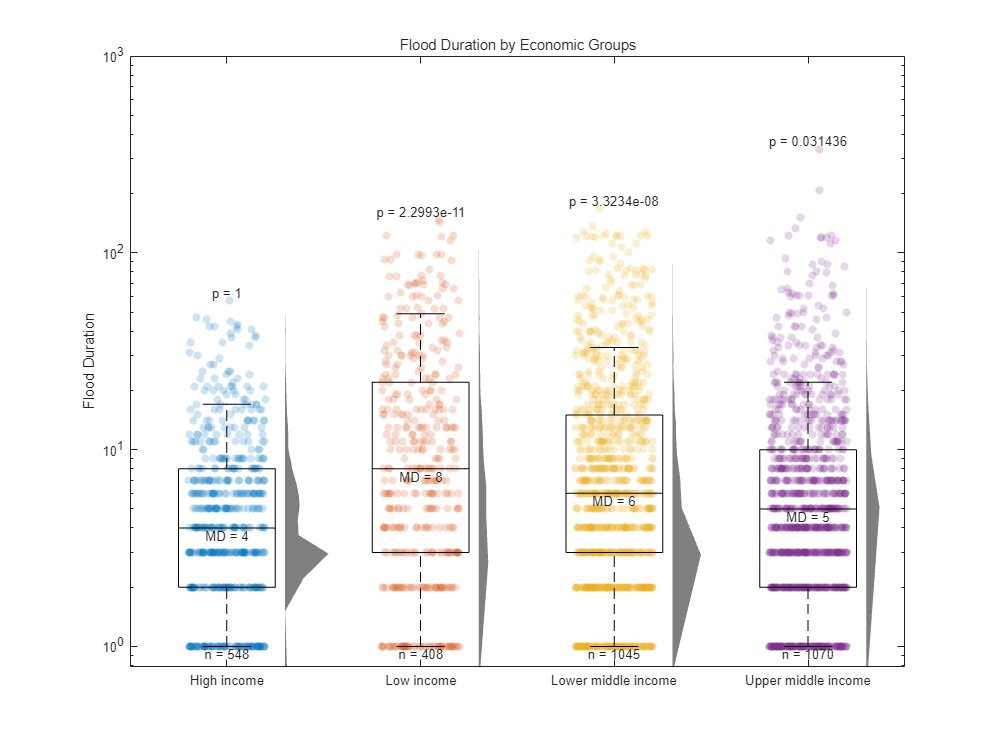


econo_div = clean_table_return_array(EMDAT_world_duration_group.IncomeGroup);
country_div = clean_table_return_array(EMDAT_world_duration_group.ISO);

duration_by_econo = containers.Map('KeyType', 'char', 'ValueType', 'any');
N_event_by_econo = zeros(length(econo_div),1);


% Loop through each category in econo_div
for i = 1:length(econo_div)
    % Get the current econo name as a string
    current_econo = char(econo_div(i));
    
    % Find the rows in the table that match the current econo
    logic_in = (EMDAT_world_duration_group.IncomeGroup == econo_div(i));
    
    % Extract the 'Duration' data for the current econo
    duration_data = EMDAT_world_duration_group.Duration(logic_in);
    duration_data = duration_data(duration_data>=1);
    N_event_by_econo(i) = length(duration_data);
    % Add the duration data to the map with the econo as the key
    duration_by_econo(current_econo) = duration_data;
end

N_event = sum(N_event_by_econo);
figure
draw_boxplot_density_scatter(duration_by_econo,N_event)

% Labels and Title
ylabel('Flood Duration');
title('Flood Duration by Economic Groups');

% Increase figure size for better visibility
set(gcf, 'Position', [100, 100, 800, 600]);




% Loop through each category in region_div
p_values = N_event_by_econo*0;
md_values = N_event_by_econo*0;

base_duration = duration_by_econo('High income');
for i = 1:length(econo_div)
    % Get the current region name as a string
    current_region = char(econo_div(i));
    
    p_values(i) = ranksum(base_duration, duration_by_econo(current_region));
    md_values(i) = median(duration_by_econo(current_region));


end


% p_values = [8.2e-08, 0.00054, 8.3e-07, 0.47];
% md_values = [9, 3, 4, 1];
n_values = N_event_by_econo;

% Loop to add p-values and MDs to the plot
for i = 1:length(econo_div)
    % Get the current region name as a string
    current_region = char(econo_div(i));
    data_i = duration_by_econo(current_region);
    text(i, max(data_i), ['p = ' num2str(p_values(i))], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
    text(i, median(data_i), ['MD = ' num2str(md_values(i))], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'top');
    text(i, min(data_i), ['n = ' num2str(n_values(i))], 'HorizontalAlignment', 'center', 'VerticalAlignment', 'cap');
end

## The number of flood events with long duration

% 提取持续时间和国家代码
durations = EMDAT_world_duration_group.Duration;
countries = EMDAT_world_duration_group.ISO;

% 唯一国家代码列表
uniqueCountries = unique(countries);

% 初始化结果变量
durationOver7 = containers.Map('KeyType','char','ValueType','double');
durationOver30 = containers.Map('KeyType','char','ValueType','double');

% 遍历每个国家
for i = 1:length(uniqueCountries)
    country = uniqueCountries(i);

    % 为当前国家找到所有事件的持续时间
    countryDurations = durations(countries==country);
    
    % 计算持续时间大于7天的事件数
    durationOver7(char(country)) = sum(countryDurations > 7);
    
    % 计算持续时间大于30天的事件数
    durationOver30(char(country)) = sum(countryDurations > 30);
end

% % 显示结果
% disp('持续时间大于7天的事件数：');
% disp(durationOver7);
% 
% disp('持续时间大于30天的事件数：');
% disp(durationOver30);

figure; 
draw_world_map(durationOver7);

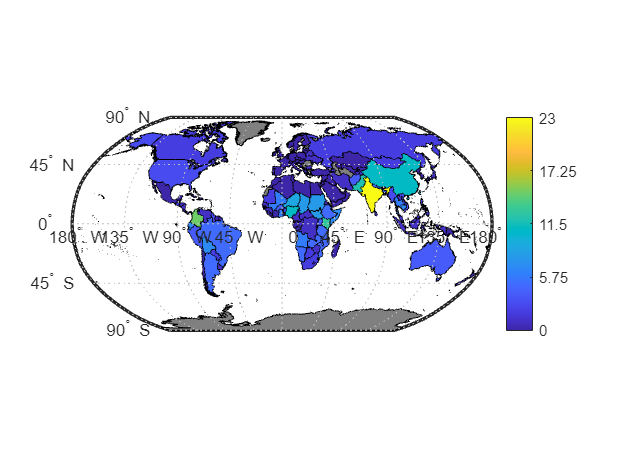


figure; 
draw_world_map(durationOver30);

function draw_world_map(country_data)
    world_country_boun_shp = "H:\Research\Data\for_dif_types\Boundary\World_countries\World_countries.shp";
    % 获取地图数据
    countries_shp = shaperead(world_country_boun_shp, 'UseGeoCoords', true);
    
    max_data = 0;
    min_data = inf;
    
    for k = 1:length(country_data)
        all_key = country_data.keys;
        data_k = country_data(cell2mat(all_key(k)));
        max_data = max(max_data,data_k);
        min_data = min(min_data,data_k);
    
    end
    
    % 初始化一个世界地图
    ax = worldmap('world');
    setm(ax, 'FFaceColor', "none"); % 设置默认背景颜色为灰色
    
    
    
    % 循环遍历所有国家
    for k = 1:length(countries_shp)
        % 查找国家名称匹配的数据值
        index = strcmp(country_data.keys, countries_shp(k).SOC);
        if any(index)
            % 如果找到匹配的国家，使用对应的数据值来计算颜色
            countryData_k = country_data(countries_shp(k).SOC);
            colorValue = countryData_k;
    
            % 这里，您需要根据实际数据范围来调整颜色映射
            c = colormap; % 获取当前颜色图
            colorIndex = fix((colorValue - min_data) / (max_data - min_data) * size(c,1));
            colorIndex = max(colorIndex, 1); % 确保索引不小于1
            % patchm(countries_shp(k).Lat, countries_shp(k).Lon, c(colorIndex, :)); % 使用计算出的颜色填充
            geoshow(countries_shp(k).Lat, countries_shp(k).Lon, 'DisplayType', 'polygon', ...
                    'FaceColor', c(colorIndex, :));
        else
            % 如果没有找到匹配的国家，就使用默认颜色
            geoshow(countries_shp(k).Lat, countries_shp(k).Lon, 'DisplayType', 'polygon', ...
                    'FaceColor', [0.5 0.5 0.5]);
        end
    end
    
    % 设置颜色条的极限为数据值的范围
    clim([min_data max_data]);
    
    % 创建颜色条并设置标签
    h = colorbar;
    numTicks = 5;
    
    set(h, 'Ticks', linspace(min_data, max_data, numTicks), ...  % numTicks是颜色条上的刻度数
            'TickLabels', arrayfun(@num2str, linspace(min_data, max_data, numTicks), 'UniformOutput', false));
    
    % 可以根据需要设置numTicks的值，例如5或10，以提供合理的颜色条刻度

end

function group_names = clean_table_return_array(categoricalArray)
    % Assuming 'categoricalArray' is your categorical array
    
    % Find the indices of undefined entries
    undefinedIndices = isundefined(categoricalArray);
    
    % Remove undefined entries from the categorical array
    group_names = unique(categoricalArray(~undefinedIndices));
end

function draw_boxplot_density_scatter(duration_by_groups,N_event)

    groups_keys = duration_by_groups.keys; % keys
    % duration_by_groups(cell2mat(groups_keys(i)))  values for key i
    groups_data = zeros(N_event,1);
    groups_label = cell(N_event,1);
    
    tag=0;
    for i = 1:length(groups_keys)
        i_group_duration = duration_by_groups(cell2mat(groups_keys(i)));
        groups_data(tag+1:tag+length(i_group_duration)) = i_group_duration;
        groups_label(tag+1:tag+length(i_group_duration)) = groups_keys(i);
        tag = tag+length(i_group_duration);
    end
    
    
    % Overlay individual data points
    for i = 1:length(groups_keys)
        i_group_duration = duration_by_groups(cell2mat(groups_keys(i)));
        xData = repmat(i, length(i_group_duration), 1); % Create x data for scatter plot
        scatter(xData, i_group_duration, 'filled', 'MarkerFaceAlpha', 0.2,'jitter','on', 'jitterAmount',0.2); % Jitter helps in better visualization
        hold on
    end
    
    
    
    % Plot boxplot
    boxplot(groups_data, groups_label,'symbol',"", 'Colors', 'k');
    
    hold on;
    
    
    
    
    % Data for density plots
    % colors = ['b', 'r', 'y', 'm', 'g']; % Define colors for each group
    max_ylim = max(get(gca, 'xlim'));
    maxf = 0;
    
    for i = 1:length(groups_keys)
        i_group_duration = duration_by_groups(cell2mat(groups_keys(i)));
        [f, xi] = ksdensity(i_group_duration,"Kernel","normal","Support",'positive',"Bandwidth",0.08); % Kernel density estimation ,"Support","positive"
        maxf = max(maxf,max(f));
    end
    
    % Plot density estimation
    for i = 1:length(groups_keys)
        i_group_duration = duration_by_groups(cell2mat(groups_keys(i)));
        [f, xi] = ksdensity(i_group_duration,"Kernel","normal","Support",'positive',"Bandwidth",0.08); % Kernel density estimation ,"Support","positive"
        f = f * (max_ylim / maxf * 0.05); % Scale factor for display
        
        xi = xi; % Adjust position for display
    
        patch('XData', [i+0.3 f+i+0.3], 'YData', [min(xi) xi], 'FaceColor', 'k', 'EdgeColor', 'none', 'FaceAlpha', 0.5);
    
    end
    
    % Log scale for y-axis
    set(gca, 'YScale', 'log');
    
    % Grid on
    % grid on;
    
    hold off;
end